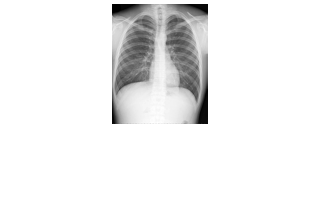

% Edge Detection
f=imread('radiograph1.jpg'); % leer la imagen original
f=imresize(f,0.25); % hacer mas pequeña la imagen
f=double(f(:,:,1)); % pasandola a doble
imshow(f,[]) % mostrar la imagen

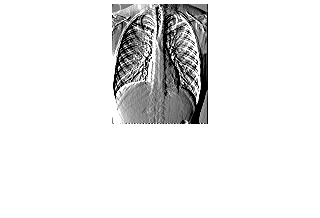

edgex=[1,-1] ;% derivada de 1 a -1, si se cambia de -1 a 1 obtenemos las derivadas al revés
g1=conv2(f,edgex,'same'); % aplicando convolución
imshow(g1,[-10,10]); % para resltar orillas contraste de -10 a 10

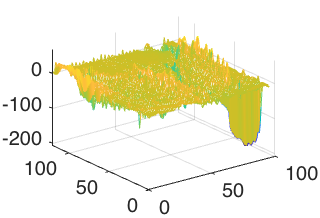

mesh(g1) % para observar derivadas positivas y negativas

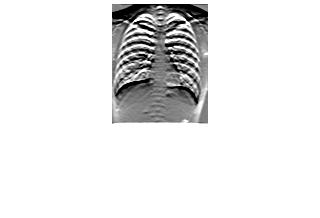

edgey=[-1 -2 -1;0,0,0;1,2,1]/8 ;% derivada e y con filtro de sobel
g2=conv2(f,edgey,'same'); % convolución en y
imshow(g2,[-10,10]) % mostrar imagen con derivada en y

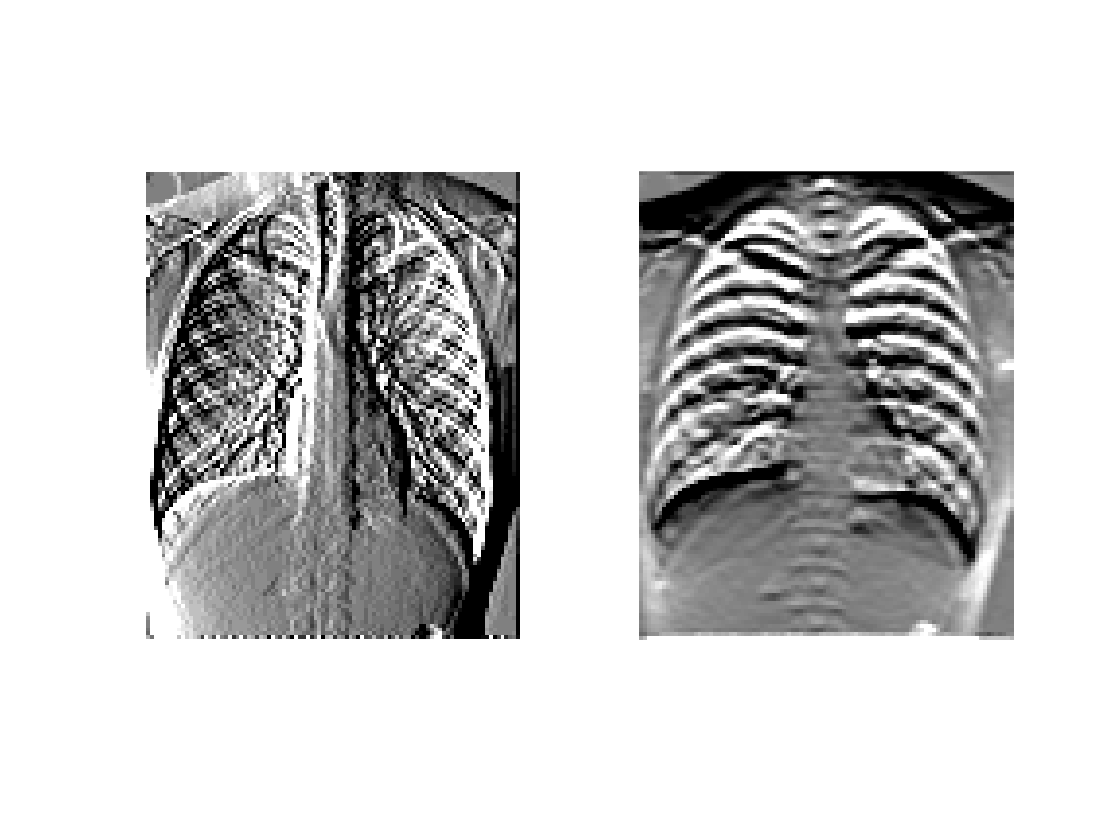

figure(2)
subplot(1,2,1)
imshow(g1,[-10,10]) % imagen con derivada en x
subplot(1,2,2)
imshow(g2,[-10,10]) % mostrar imagen con derivada en y para hacer una comparación con derivada en x

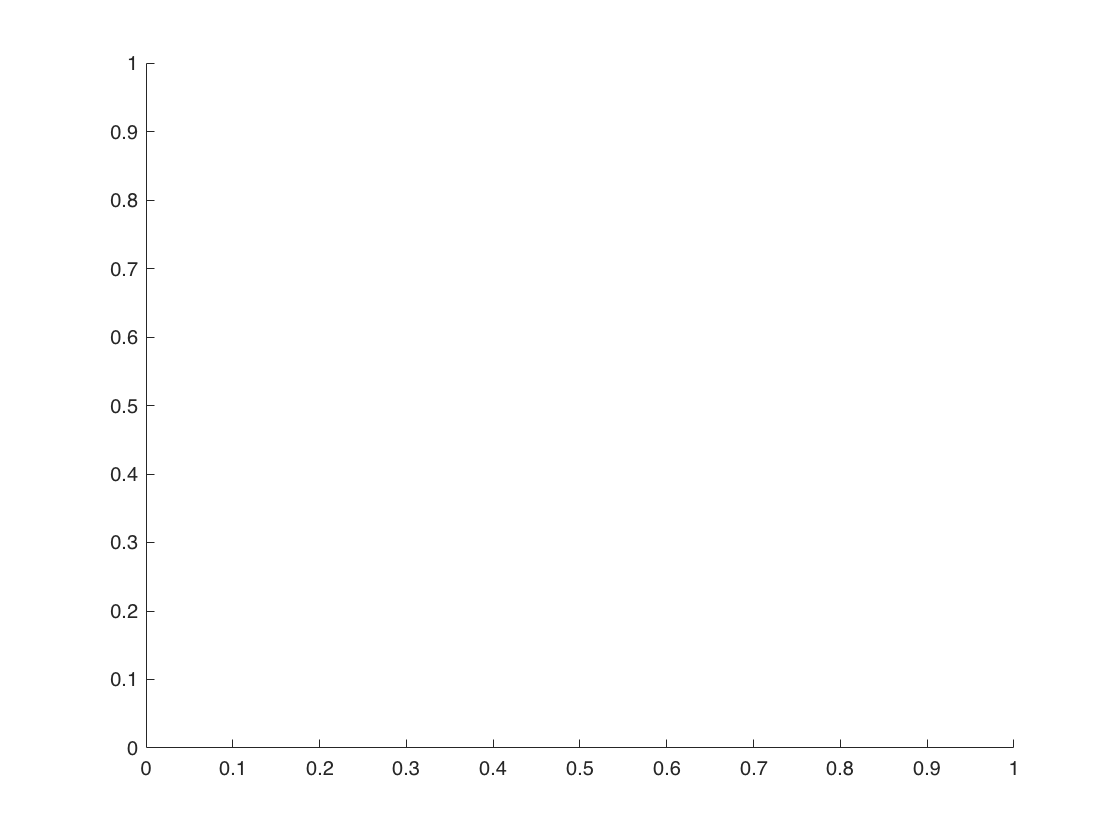

figure(3)
subplot(1,1,1)

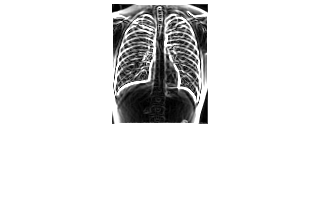

edgex=[1,0,-1;2,0,-2;1,0,-1]/8  ;% derivada en x con sobel
gx=conv2(f,edgex,'same'); % convolución en x
gy=conv2(f,edgey,'same'); % convolución en y
% mag=(abs(gx)+abs(gy))/2; % magnitud del gradiente, diviendo entre 2 porque hay dos gradientes y mantener la misma escala
mag = sqrt(gx.^2 + gy.^2) ;% manera correcta de calcular la magnitud del gradiente
%realizar un imshow para mostrar la magnitud del gradiente:

imshow(mag,[0,20]); % mostrar magnitud del gradiente

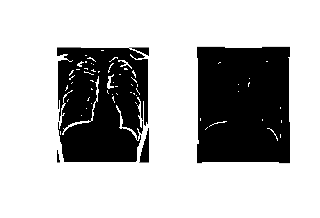

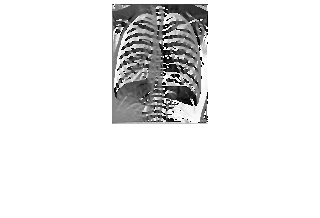

noisemask = [-1, 0 1]; % mascara llamativa sencilla
noiseimage = conv2(f,noisemask,'same'); % convolucion con mascara para obteneer diferencia entre pixel y pixel
noisevariance = mean2(noiseimage.^2); % calculando varianza la cual es igual a la media de la imagen al cuadradro
noisestd = sqrt(noisevariance/2); % calculando desviacion estandar la cual es igual a la raiz cuadrada de la varianza entre 2
edgedetection1 = mag > noisestd; % orilla con umbral 
edgedetection2 = mag > 2*noisestd; % orilla con 2 estandar desviaciones
subplot(1,2,1)
imshow(edgedetection1,[]); % plot de la primera orilla
subplot(1,2,2)
imshow(edgedetection2,[]); % plot de la segunda orilla
figure(4)
subplot(1,1,1)
angle=atan2(gy,gx); % calculando el ángulo con arctan2 del gradiente en y y en x, resultados estan en radianes
imshow(angle,[]);

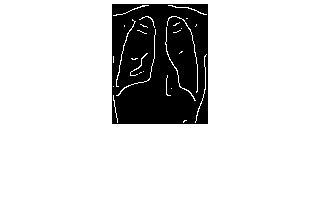

 % Detección de orillas por Canny (canny edge detector) dependiendo de los parametros que se le pongan
edgcany=edge(f,'Canny',0.1,3);
imshow(edgcany,[]);

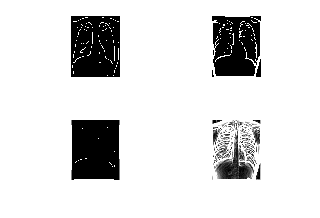

% se  realiza un subplot de los resultados obtenidos anteriormente para asi visualizar diferencias y realizar una comparación
subplot(2,2,1) 
imshow(edgcany,[])
subplot(2,2,2)
imshow(edgedetection1,[])
subplot(2,2,3)
imshow(edgedetection2,[])
subplot(2,2,4)
imshow(mag,[0,10])